Te = 1/50;
k=2;
wn=5;
theta=0.7;
num = [k*wn^2]

num = 50

den = [1 2*theta*wn wn^2]

den =      1     7    25



[numd, dend] = c2dm(num, den, Te, 'zoh');
tfd1 = tf(numd, dend, Te)


tfd1 =
 
  0.009541 z + 0.009106
  ---------------------
  z^2 - 1.86 z + 0.8694
 
Sample time: 0.02 seconds
Discrete-time transfer function.


[numd, dend] = c2dm(num, den, Te, 'foh');
tfd2 = tf(numd, dend, Te)


tfd2 =
 
  0.003218 z^2 + 0.01243 z + 0.003001
  -----------------------------------
         z^2 - 1.86 z + 0.8694
 
Sample time: 0.02 seconds
Discrete-time transfer function.


[numd, dend] = c2dm(num, den, Te, 'tustin');
tfd3 = tf(numd, dend, Te)


tfd3 =
 
  0.004662 z^2 + 0.009324 z + 0.004662
  ------------------------------------
         z^2 - 1.86 z + 0.8695
 
Sample time: 0.02 seconds
Discrete-time transfer function.


[numd, dend] = c2dm(num, den, Te, 'matched');
tfd4 = tf(numd, dend, Te)


tfd4 =
 
  0.009324 z + 0.009324
  ---------------------
  z^2 - 1.86 z + 0.8694
 
Sample time: 0.02 seconds
Discrete-time transfer function.


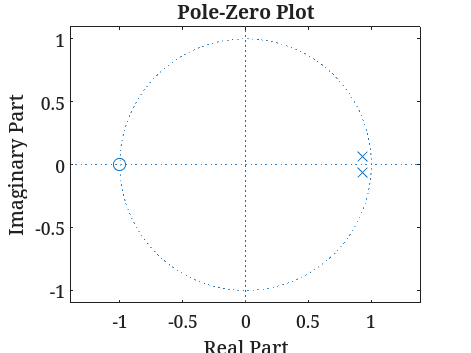


zplane(numd, dend)